# **Demo_01:**    Gyroscopic Boat stabilizer - Equation of motion derivation

In this **example** we're going to use **Lagrange's equation** to derive the equations of motion for a **gyroscopic boat stabilizer**.  Specifically we're going to:

- Compute the Kinetic and Potential energy of the system

- Compute the Generalised Forces of the system

- Derive the equations of motion using's Lagrange's method

The system that we're going to explore is shown in Figure 1 below.  We have a gyroscope attached to the boat's hull

**Figure 1:   The gyroscopic boat stabilizer**

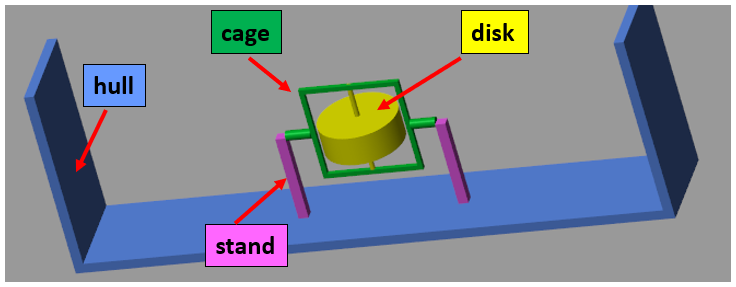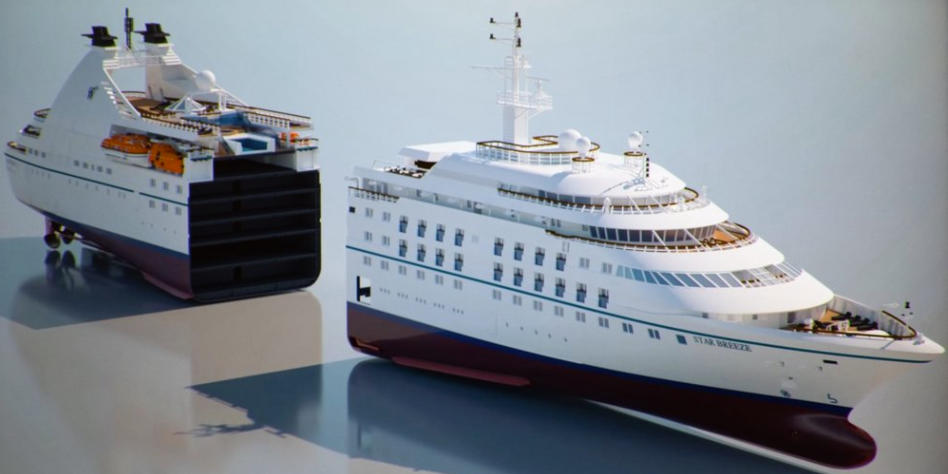

*REF:   photograph source   *[*https://www.seattletimes.com/business/stretching-a-small-cruise-ship/*](https://www.seattletimes.com/business/stretching-a-small-cruise-ship/)

`Bradley Horton : 20-Aug-2020, bhorton@mathworks.com`

## Introducing the Gyroscopic boat stabilizer

The generalised co-ordinates that we'll use to desribe the system are:     $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$

**NOTE the following**:

- The Inertial **W-frame** has it's origin at point O.  The **H-frame** has the same origin as the W-frame.

- The **H-frame** is body fixed to the Hull. The H-frame rotates relative to the W-frame by $\theta$. (see **Figure 2a**)

- The **C-frame** is body fixed to the Cage's CoM.  The C-frame rotates relative to the H-frame by $\phi$.  (see **Figure 2b**)

- The **D-frame** is body fixed to the Disk's CoM.  The D-frame rotates relative to the C-frame by $\beta$.  (see **Figure 2c**)

- A disturbance torque $\tau_{\textrm{HULL}}$ is applied to the hull.  This mimics the excitation caused by a wave.  (see **Figure 2a**)

- The disk is excited by a motor torque $\tau_{\textrm{DISK}}$ .  (see **Figure 2c**)

-       $\Longrightarrow$ and equal and opposite torque is applied to the cage

   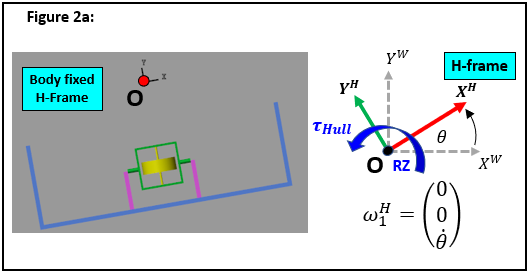 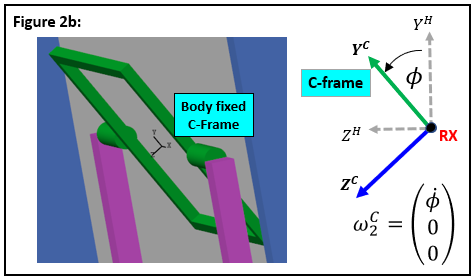

  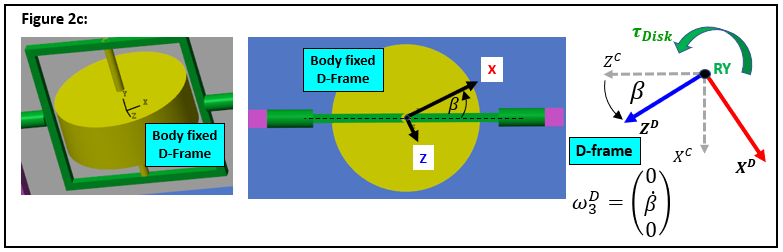

### Define some symbolic variables for deriving the equations of motion

The corresponding symbolic variables that we'll use are:

syms      m_hull        m_disk   m_cage
syms    tau_hull      tau_disk
syms y_CG_H_hull   y_CG_H_disk              % (m) - y-co-ordinate of CoMs in the H-frame
syms g                                      % (m/sec^2)

syms   THETA(t)  theta   % (radians)
syms   PHI(t)    phi     % (radians)  
syms   BETA(t)   beta    % (radians)  


Symbols for angular velocties and accelerations

syms   theta_dot    phi_dot   beta_dot   % (radians/sec)
syms   theta_ddot   phi_ddot  beta_ddot  % (radians/sec^2)   

Lists of symbols

% actual_list = [  THETA(t),   diff(THETA(t), t),      diff(THETA(t), t,2), ...
%                    PHI(t),   diff(  PHI(t), t),      diff(  PHI(t), t,2), ...
%                   BETA(t),   diff( BETA(t), t),      diff( BETA(t), t,2)     ];
% 
% pretty_list = [    theta,       theta_dot,            theta_ddot, ...
%                      phi,         phi_dot,              phi_ddot, ...
%                     beta,        beta_dot,             beta_ddot           ];


actual_list = [  diff(THETA(t), t,2), diff(THETA(t), t),  THETA(t),  ...
                 diff(  PHI(t), t,2), diff(  PHI(t), t),    PHI(t),  ...
                 diff( BETA(t), t,2), diff( BETA(t), t),   BETA(t),           ];

pretty_list = [    theta_ddot,                theta_dot,    theta,   ...
                     phi_ddot,                  phi_dot,      phi,   ...
                    beta_ddot,                 beta_dot,      beta            ];


### Compute translational velocities of CoMs for the hull, cage and disk

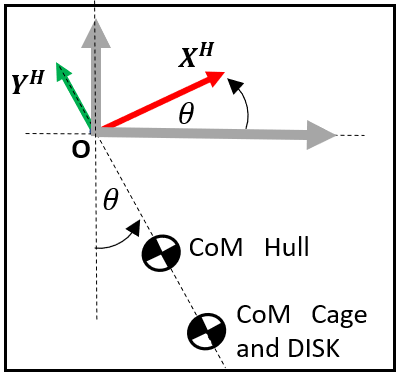

- The translational velocity for all three bodies can be computed using   $v=\omega \times r$

- The velocties will be expressed in components of the H-frame.     

v_cg_H_hull =  cross( [0;0;theta_dot], [0;y_CG_H_hull;0] );
v_cg_H_disk =  cross( [0;0;theta_dot], [0;y_CG_H_disk;0] );
v_cg_H_cage =  cross( [0;0;theta_dot], [0;y_CG_H_disk;0] ); % cage COM is same as disk Com

### Compute angular velocities for the hull, cage and disk  

We now need to define the angular velocities of the three bodies for this system.  We'll attach body-fixed frames to the center of masses of each body and then describe how to orientate the body into an "arbitrary" pose(subject to its constraints) using **Euler angles**.  We'll use a $Z_1 \longrightarrow X_2 \longrightarrow Y_3$ Euler angle sequence.  For example, the relationship between a vector defined in the Inertial {W-frame} and the components of that same vector expressed in the body-fixed {D-frame} attached to the CoM of the disk, is:

- 
$${}^Dv\;\;=\;\;\left\lbrack R_{3Y} \left(\beta \right)\right\rbrack \;\ldotp \left\lbrack R_{2X} \left(\phi \right)\right\rbrack \;\ldotp \left\lbrack R_{1Z} \left(\theta \right)\right\rbrack \;\ldotp \;{}^Wv$$


**NOTE: ** Passive rotation matrices are defined in the subfunctions  `LOC_get_RX()`  and `LOC_get_RY()` at the bottom of this script.

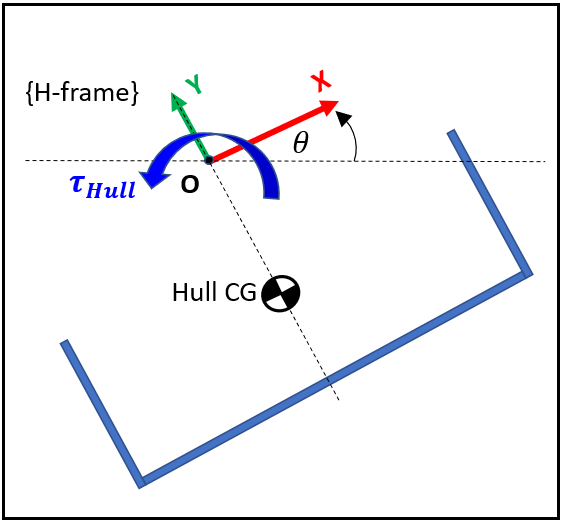 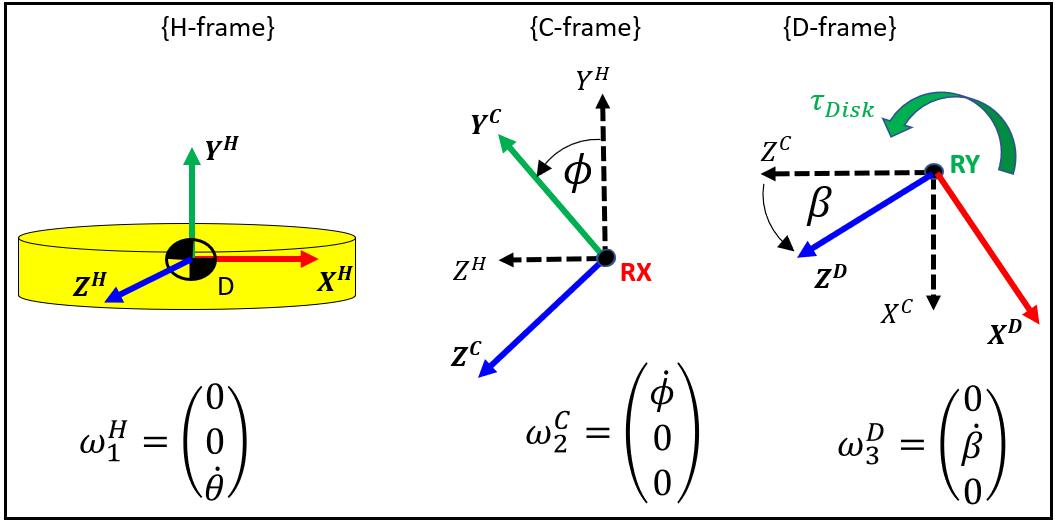

**The hull:**

The total angular velocity of the hull expressed in components of the {H-frame} , is:

omega_H_hull = [0;0;theta_dot];

**The cage:**

The total angular velocity of the cage will be expressed in components of the {C-frame}:

- 
$${}^C{\omega }_{\textrm{CAGE}}\;\;=\;\;R_X \left(\phi \right)\ldotp {}^H{\omega }_1\;\;\;\;+\;\;\;\;\;{}^C{\omega }_2\;\;\;\;\;\;$$


omega_C_cage = LOC_get_RX(phi)*omega_H_hull +  [phi_dot;0;0];         

**The disk:**

The total angular velocity of the disk will be expressed in components of the {D-frame}:

- 
$${}^D{\omega }_{\textrm{DISK}}\;\;=\;\;R_Y \left(\beta \right)\ldotp R_X \left(\phi \right)\ldotp {}^H{\omega }_1\;\;\;\;+\;\;\;\;\;R_Y \left(\beta \right)\ldotp {}^C{\omega }_2\;\;\;\;\;\;+\;\;\;\;\;\;{}^D{\omega }_3$$


omega_D_disk =  LOC_get_RY(beta)*LOC_get_RX(phi)*omega_H_hull + ...
                LOC_get_RY(beta)*[phi_dot;0;0]                + ...
                [0;beta_dot;0]

$$omega\_D\_disk = \left(\begin{array}{c} \dot{\varphi }\,\cos\left(\beta \right)-\dot{\theta }\,\cos\left(\varphi \right)\,\sin\left(\beta \right)\\ \dot{\beta }+\dot{\theta }\,\sin\left(\varphi \right)\\ \dot{\varphi }\,\sin\left(\beta \right)+\dot{\theta }\,\cos\left(\beta \right)\,\cos\left(\varphi \right) \end{array}\right)$$

### Compute the system Kinetic energy

If we attach BODY fixed frames to the **centre of masses** of each body in our system, then the kinetic energy for the $i^{\textrm{th}}$ body can be stated as:

- 
$${\textrm{KE}}_i \;\;\;=\;\;\;\;\;\frac{1}{2}v_{{\textrm{cm}}_i }^T {\ldotp \;m}_i {\;\ldotp v}_{{\textrm{cm}}_i } \;\;\;+\;\;\;\;\;\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{\textrm{cm}}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual kinetic energies.   ${\textrm{KE}}_{\textrm{system}} \;\;\;=\;\;\;\;\sum_{i=1}^N {\textrm{KE}}_i$       

KE = (0.5)*  v_cg_H_hull(:).' * m_hull            *  v_cg_H_hull(:)  + ...
     (0.5)*  v_cg_H_disk(:).' * m_disk            *  v_cg_H_disk(:)  + ...
     (0.5)*  v_cg_H_cage(:).' * m_cage            *  v_cg_H_cage(:)  + ...
     (0.5)* omega_H_hull(:).' * LOC_get_Ig_H_hull * omega_H_hull(:)  +  ...
     (0.5)* omega_D_disk(:).' * LOC_get_Ig_D_disk * omega_D_disk(:)  +  ...
     (0.5)* omega_C_cage(:).' * LOC_get_Ig_C_cage * omega_C_cage(:)  ;  

### Compute the system Potential energy

The center of mass of the hull, cage and disk have potential energy.  We'll define the "reference" datum (ie: $\textrm{PE}=0$) at the $\theta =0$ position as shown below:

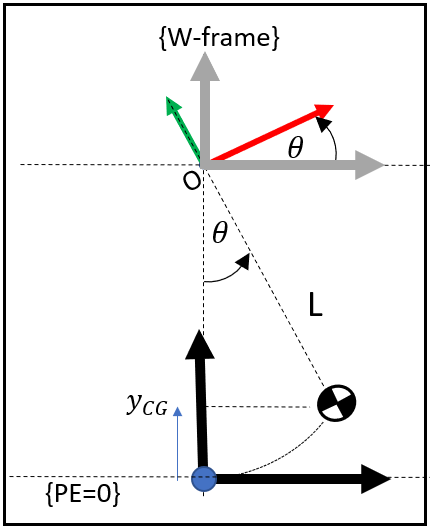      Therefore the potential energy for the $i^{\textrm{th}}$ body can be stated as:

- 
$${\textrm{PE}}_i \;=\;\int_{y_{i\_\textrm{CG}} }^0 \;-m_i \;\ldotp g\ldotp \textrm{dy}\;\;=\;\;\;m_i \ldotp g\ldotp y_{i\_\textrm{CG}} \;\;=\;\;\;$$

$$m_i \ldotp g\ldotp \left(L_i \;\;-\;L_i \ldotp \cos \left(\theta \right)\right)$$


L_hull_com = sqrt(y_CG_H_hull^2);
L_disk_com = sqrt(y_CG_H_disk^2);
L_cage_com = L_disk_com;

PE = m_hull*g*(L_hull_com - L_hull_com*cos(theta)) + ...
     m_disk*g*(L_disk_com - L_disk_com*cos(theta)) + ...
     m_cage*g*(L_cage_com - L_cage_com*cos(theta));

### Define the system Lagrangian:

 L = KE - PE;

There are alot of terms in the Lagrangian - check it out:

 L

# Implement Lagrange's equation:

The Euler-Lagrange equation can be stated as:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;\;={\;\;\;Q}_k$    for  $k=1,2,\cdots ,n$

where:  *n* is the number of DOFs of the system,    {$q_1, q_2, \dots, q_n$} is a set of **Generalized Co-ordinates**,    and  {$Q_1, Q_2, \dots, Q_n$} is the set of  **Generalised Forces** associated with those co-ordinates, and the Lagrangian:  ***L***** =  KE  *****-*****  PE***,* is defined as the difference between the Kinetic and Potential energy of the  *n-* DOF system.  The Generalised forces can also be defined in terms of the non conservative forces and torques acting on the multibody system.  The formula for the **Generalised Forces** acting on the system is:

- 
$$Q_k \;\;\;=\;\;\;\sum_{i=1}^{{\textrm{Nf}}_{\textrm{nc}} } \left(\vec{F_i } \;\;\ldotp \;\frac{\partial \vec{v_i } }{\partial \dot{q_k } }\right)\;\;\;+\;\;\;\;\;\;\sum_{j=1}^{{N\tau }_{\textrm{nc}} } \left(\vec{\tau_j } \;\;\ldotp \;\frac{\partial \vec{\omega_j } }{\partial \dot{q_k } }\right)\;$$


where:

- $Q_k$     :   is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative **pure** TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

 **NOTE:**  we'll produce equations in the order  $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$

### Compute the LHS of Lagranges equation:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }$   we'll perform these computations in the subfunction `LOC_do_LHS_lag_eqn` 

EOM_LHS(1) = LOC_do_LHS_lag_eqn(L, actual_list, pretty_list, theta, theta_dot);
EOM_LHS(2) = LOC_do_LHS_lag_eqn(L, actual_list, pretty_list,   phi,   phi_dot); 
EOM_LHS(3) = LOC_do_LHS_lag_eqn(L, actual_list, pretty_list,  beta,  beta_dot); 

### Compute the RHS of Lagranges equation:

Recall that we apply external torques to the **hull** and the spinning **disk**.  The **cage** also experiences an equal but opposite disk torque(eg: an electric motor is attached to the cage). 

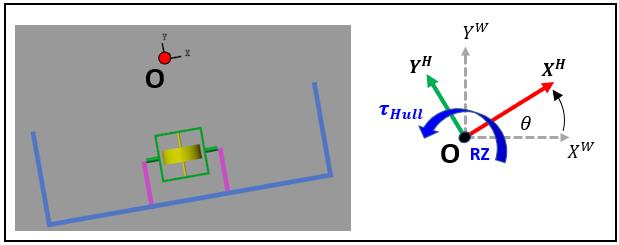  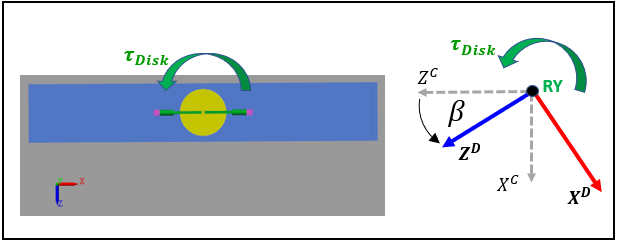

Now compute the Generalised Forces:

- 
$$Q_k \;\;\;=\;\;\;\sum_{i=1}^{{\textrm{Nf}}_{\textrm{nc}} } \left(\vec{F_i } \;\;\ldotp \;\frac{\partial \vec{v_i } }{\partial \dot{q_k } }\right)\;\;\;+\;\;\;\;\;\;\sum_{j=1}^{{N\tau }_{\textrm{nc}} } \left(\vec{\tau_j } \;\;\ldotp \;\frac{\partial \vec{\omega_j } }{\partial \dot{q_k } }\right)$$


 The two matrices below define the external torques $\tau$ and the angular velocities $\omega$ of the bodies these torques are applied to.

tmp_TQ_mat = [    0,                  0,               0;
                  0,                  tau_disk,       -1*tau_disk;
                  tau_hull,           0,               0;           ];


tmp_w_mat  = [  omega_H_hull(:),   omega_D_disk(:),   omega_C_cage(:) ];

And now let's accumulate the Generalised Forces:

-  **NOTE:**  we'll produce equations in the order  $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$

EOM_RHS = sym([0,0,0]);

for kk=1:size(tmp_TQ_mat, 2)
    
   TQ_col         = tmp_TQ_mat(:,kk);
   w_col          = tmp_w_mat(:,kk);
   
   TQ_col = subs(TQ_col, actual_list, pretty_list);
   w_col  = subs( w_col, actual_list, pretty_list);
   
   dw_dtheta_dot =  diff(w_col, theta_dot);
   dw_dphi_dot   =  diff(w_col,   phi_dot);
   dw_dbeta_dot  =  diff(w_col,  beta_dot);
   
   EOM_RHS(1)    = EOM_RHS(1) +  sum( TQ_col .*  dw_dtheta_dot);
   EOM_RHS(2)    = EOM_RHS(2) +  sum( TQ_col .*  dw_dphi_dot);  
   EOM_RHS(3)    = EOM_RHS(3) +  sum( TQ_col .*  dw_dbeta_dot);
end

### Combine the LHS and RHS parts together

Let's get everything presented in "pretty symbols"

EOM_RHS = subs(EOM_RHS, actual_list, pretty_list);
EOM_LHS = subs(EOM_LHS, actual_list, pretty_list);

EOM_RHS = EOM_RHS(:);
EOL_RHS = EOM_LHS(:);

 OK:  Let's equate the LHS and RHS of Lagranges equation:

my_sys_EQ = EOL_RHS == EOM_RHS ; 
my_sys_EQ = simplify(my_sys_EQ)

### Present the system equations of motion

Let's rearrange our equations into the form:

- $A\ldotp x=b$     where     $x={\left\lbrack \begin{array}{ccc}
\ddot{\theta}  & \ddot{\phi}  & \ddot{\beta} 
\end{array}\right\rbrack }^T$

VAR_SYS      = [theta_ddot, phi_ddot, beta_ddot]; 
[my_A, my_b] = equationsToMatrix(my_sys_EQ, VAR_SYS)

We can now numerically solve these equations using the following process:

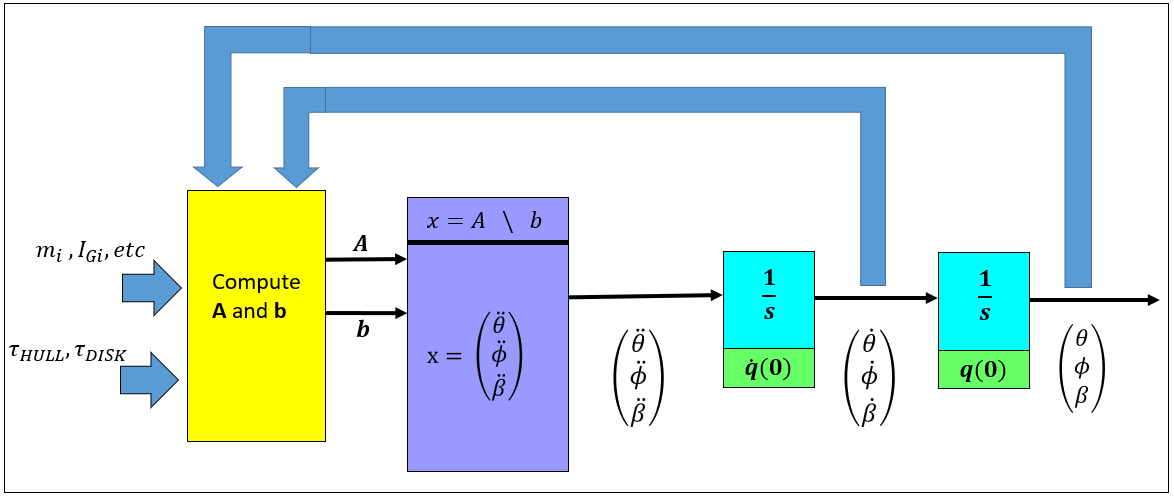

### And convert into a Simulink block:

In the next DEMO, we're going to simulate the dynamics of this system, i.e.: we'll specify numeric values for our model parameters and we'll stimulate the system with time vaying torques $\tau_{\textrm{HULL}} ,\;\tau_{\textrm{DISK}}$ .  Although we could perform this simulation in MATLAB, there is another (even easier) way - it's called **Simulink**.  But in order to use Simulink we need a way of importing our derived equations of motion.  Rather than writing out by hand the derived equations, we'll use the [`matlabFunctionBlock()`](matlab:  web(fullfile(docroot, 'symbolic/matlabfunctionblock.html'))) function to automatically convert these equations into a MATLAB Function block.  Conceptually we're going to perform the task shown below:

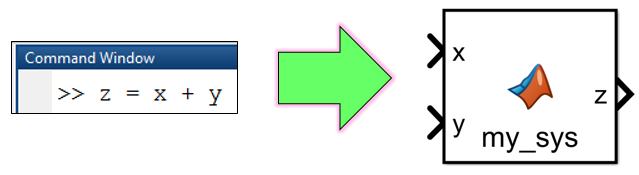     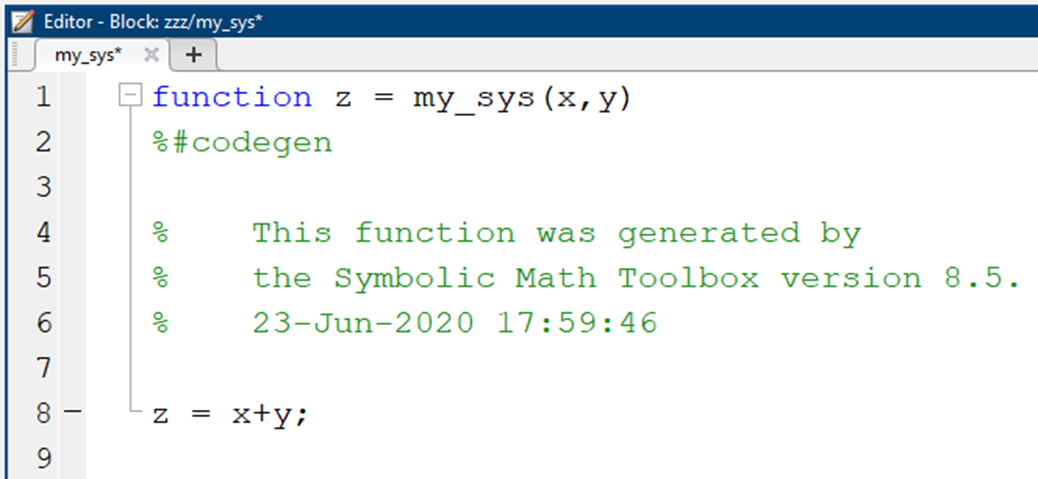

But in our case, the expressions that we'll be creating a block of are the expressions for are $A$ and $b$ matrices defined above.

tf_i_should_create_SL_block = true;

OK, let's do it:

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_Ab';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_A_and_b'], ...
                         my_A,    my_b,  ...
                        'Outputs',  {'A', 'b'},  ...
                        'Optimize', false );
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_A_and_b'],'BackgroundColor','[1, 1, 0.607843]')
end

# Explore the Gyroscopic Stabilizing Torques:

Before wrapping up this first example/demo,let's revisit our system of equations stored in `my_sys_EQ`  - recall that we derived these for the generalised co-ordinates in the order  $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$.  First, let's set the ***Product of Inertias to ZERO*** for the disk - because the disk has an axis if symmetry.

my_new_EQ_sys = LOC_set_inertia_products_to_zero(my_sys_EQ);

Next, I'd like to look at any terms that contain the disk inertia $I_{{\textrm{DISK}}_{\textrm{YY}} }$ .... because this is the inertia term that we "associate" with the spinning disk.

syms  Idisk_yy

tmp_c1 = coeffs( lhs(my_new_EQ_sys(1)), Idisk_yy, 'All' ).';
tmp_c2 = coeffs( lhs(my_new_EQ_sys(2)), Idisk_yy, 'All' ).';
tmp_c3 = coeffs( lhs(my_new_EQ_sys(3)), Idisk_yy, 'All' ).';
whos tmp_c*

  Name        Size            Bytes  Class    Attributes

  tmp_c1      1x1                 8  sym                
  tmp_c2      1x1                 8  sym                
  tmp_c3      1x1                 8  sym                



OK, so each of our 3 equations contain terms that involve $I_{{\textrm{DISK}}_{\textrm{YY}} }$ , so let's inspect them:

Remember the order of our equations:   $q_k =\left\lbrace \theta ,\;\;\phi ,\;\;\beta \right\rbrace$

[tmp_c1(1);  tmp_c2(1);  tmp_c3(1)]

NOTE the presence of $\dot{\beta}$ as this represents the spinning disk angular velocity.  

#### OBSERVATION_01:    What happens when $\phi ={90}^{\circ }$

- When $\phi ={90}^{\circ }$ we have  $\cos \left(\phi \right)==0$  and  $\sin \left(2\phi \right)==0$

- So ? - so when $\phi ={90}^{\circ }$, the stabilizing torque on our $\ddot{\theta}$ equation goes to zero, i.e.  $0==\dot{\beta} \ldotp \dot{\phi} \ldotp \cos \left(\phi \right)$   AND   $0==\dot{\phi} \ldotp \dot{\theta} \ldotp \sin \left(2\phi \right)$

#### OBSERVATION_02:    What happens when $\dot{\phi} =0\;$

- When we prevent the cage from "precessing" we have  $\dot{\phi} =0$

- So ? - so when $\dot{\phi} =0$, the stabilizing torque on our $\ddot{\theta}$ equation goes to zero, i.e $0==\dot{\beta} \ldotp \dot{\phi} \ldotp \cos \left(\phi \right)$ AND $0==\dot{\phi} \ldotp \dot{\theta} \ldotp \sin \left(2\phi \right)$

# **Next Steps**

Now that we've derived the equations of motion for the boat stabilization system.  The next step is to solve/simulate these equations.

- 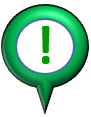In the file [`DEMO_02_bh_boat_stabilizer_Simulate.mlx`](matlab: edit('DEMO_02_bh_boat_stabilizer_Simulate.mlx')) we'll show you how this can be done

# Local subfunctions only beyond this point:

Define the Inertia matrix for the Hull about it's Com

function Ig = LOC_get_Ig_H_hull

    syms Ihull_xx   Ihull_yy   Ihull_zz
    syms Ihull_xy   Ihull_xz   Ihull_yz
    
    Ig = [ Ihull_xx,    Ihull_xy,    Ihull_xz;   
           Ihull_xy,    Ihull_yy,    Ihull_yz;
           Ihull_xz,    Ihull_yz,    Ihull_zz; ];
end

Define the Inertia matrix for the Disk about it's Com

function Ig = LOC_get_Ig_D_disk

    syms Idisk_xx   Idisk_yy   Idisk_zz
    syms Idisk_xy   Idisk_xz   Idisk_yz
    
    Ig = [ Idisk_xx,    Idisk_xy,    Idisk_xz;   
           Idisk_xy,    Idisk_yy,    Idisk_yz;
           Idisk_xz,    Idisk_yz,    Idisk_zz; ];
       
%     Ig = [ Idisk_xx,    0,           0;   
%            0,           Idisk_yy,    0;
%            0,           0,           Idisk_zz; ];       

end

Define the Inertia matrix for the Cage about it's Com

function Ig = LOC_get_Ig_C_cage

    syms Icage_xx   Icage_yy   Icage_zz
    syms Icage_xy   Icage_xz   Icage_yz
    
    Ig = [ Icage_xx,    Icage_xy,    Icage_xz;   
           Icage_xy,    Icage_yy,    Icage_yz;
           Icage_xz,    Icage_yz,    Icage_zz; ];
       
%     Ig = [ Icage_xx,    0,           0;   
%            0,           Icage_yy,    0;
%            0,           0,           Icage_zz; ];       

end

Define the passive Rotation matrix - $R_X \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_X \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RX(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1X'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Y \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Y \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RY(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Y'}, a, 'SYM');
    R   = OBJ.get_R;
end

Define the passive Rotation matrix - $R_Z \;\;\;\textrm{where}\;\;\;\;{}^Bv=\;\left\lbrack R_Z \left(a\right)\right\rbrack \;\ldotp \;{}^Gv$

function R = LOC_get_RZ(a)

    OBJ = bh_rot_passive_G2B_CLS({'D1Z'}, a, 'SYM');
    R   = OBJ.get_R;
end

Implement the LHS of Lagranges equation for a single generalise co-ordinate, i.e. compute the following:

- $\frac{d}{\mathrm{d}t}\left(\frac{\partial L}{\partial {\dot{q} }_k }\right)\;-\;\frac{\partial L}{\partial q_k }\;$       **Click me to go back to the analysis**

function EOM_LHS = LOC_do_LHS_lag_eqn(L_ORIGINAL, actual_list, pretty_list, q, q_dot)
    syms t

    L                 = subs(L_ORIGINAL,  actual_list, pretty_list);
    dLdqdot           = diff(L,       q_dot);
    dLdqdot           = subs(dLdqdot,  pretty_list, actual_list);    
    der_dt_of_dLdqdot = diff(dLdqdot, t);
    dLdq              = diff(L, q);
    dLdq              = subs(dLdq,    pretty_list, actual_list);
    
    EOM_LHS           = der_dt_of_dLdqdot - dLdq;
    EOM_LHS           = simplify( EOM_LHS );
end

Set the Products of inertia for the DISK to zero, i.e.  $I_{\textrm{XY}} =I_{\textrm{XZ}} =I_{\textrm{YZ}} =0$

function new_some_sys = LOC_set_inertia_products_to_zero(some_sys)

    syms Idisk_xy   Idisk_xz   Idisk_yz

    new_some_sys = subs(some_sys, [Idisk_xy, Idisk_xz, Idisk_yz],[0,0,0]);

end